## Prueba de raíces

Encontrar raíces de $f\left(x\right)=x^3 +x-1$

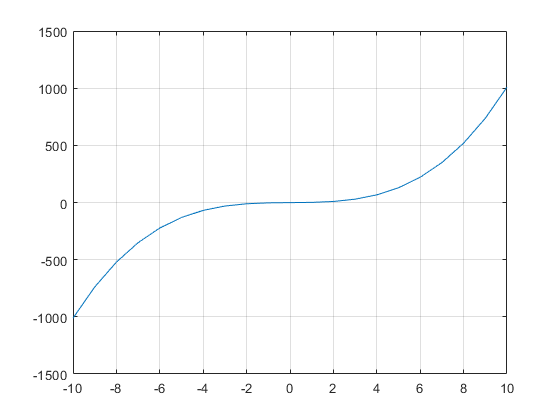

%Primera opción: Graficamos la función
x = -10:10;
f = x.^3 + x - 1;
plot(x,f)
grid on

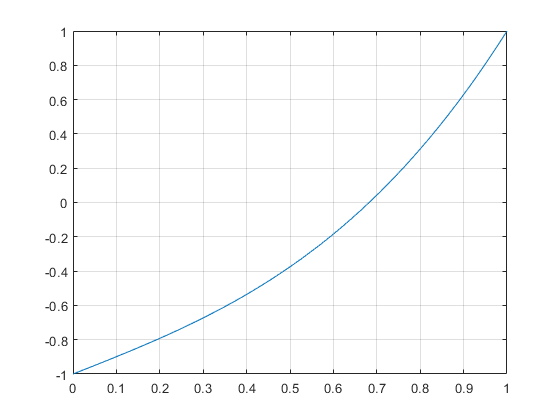

%otra alternativa para graficar

f = @(x) x.^3 + x - 1;
a = 0;
b = 1;
fplot(f, [a b])
grid on

%usando el método de bisección
format long
[x, i] = Biseccion(f, .6, .8)

x =    0.682327803828019


i =     49


f(x)

ans =      0



%usando el método de interpolación
[x, i] = interpolacionLineal(f, .6, .8)

x =    0.682327803828019


i =     16


f(x)

ans =     -1.110223024625157e-16



%usando el método de newton raphson
%es el más rápido
[x,i] = newtonRaphson(f, .6, .8)

x =    0.682327803828019


i =      5


f(x)

ans =     -1.110223024625157e-16
